# RVC2: Chapter 16 - Advanced Visual Servoing

## 16.1 XY/Z partitioned IBVS

sl_partitioned

sim('sl_partitioned')


## 16.2 IBVS Using Polar Coordinates

cam = CentralCamera('default')

principal point not specified, setting it to centre of image plane
cam = 
name: default [central-perspective]                     
  focal length:   0.008                                 
  pixel size:     (1e-05, 1e-05)                        
  principal pt:   (512, 512)                            
  number pixels:  1024 x 1024                           
  pose:           t = (0, 0, 0), RPY/yxz = (0, 0, 0) deg


T_C0 = SE3(-0.3, 0.2, -2)*SE3.Rz(pi/2);
vs = IBVS_polar(cam, 'pose0', T_C0)

vs = 
Visual servo object: camera=default
   iterations, 0 history
  P= -0.25       -0.25        0.25        0.25              
     -0.25        0.25        0.25       -0.25              
         0           0           0           0              
  C_T0:   t = ( -0.3,  0.2,  -2), R = ( 90deg |  0,  0,  1) 


creating new figure for camera


h =   Axes with properties:

             XLim: [0 1024]
             YLim: [0 1024]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties

make axes


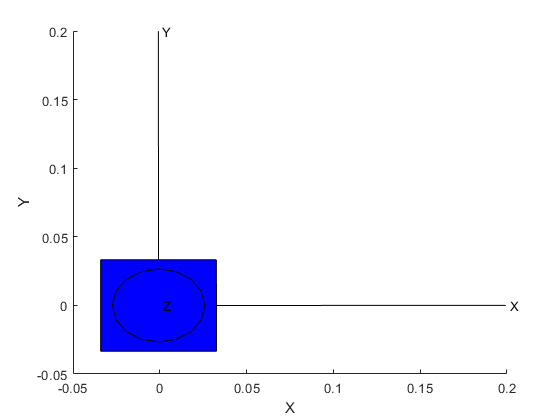

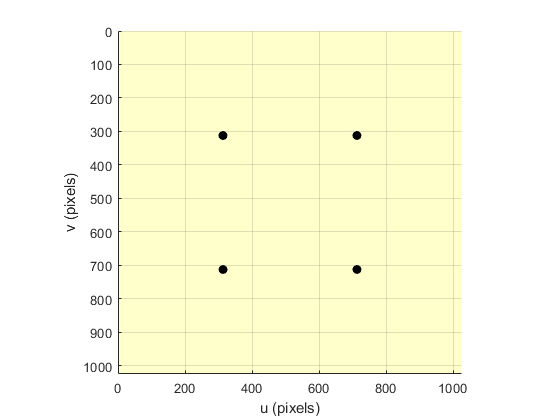

completed on error tolerance



vs.run()

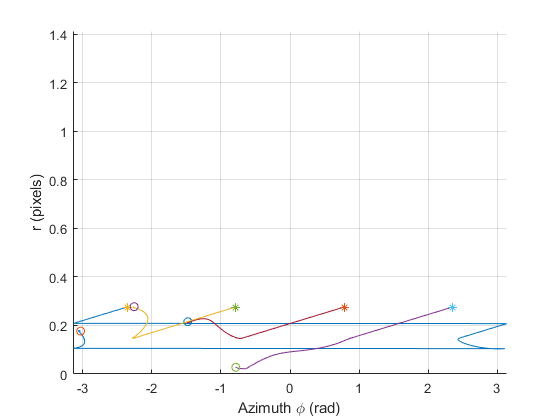

principal point not specified, setting it to centre of image plane
cam = 
name: spherical-default [spherical]                     
  pixel size:     (1, 1)                                
  pose:           t = (0, 0, 0), RPY/yxz = (0, 0, 0) deg



vs.plot_features()

## 16.4.1 Application: Arm-Type Robot

principal point not specified, setting it to centre of image plane


creating new figure for camera


h =   Axes with properties:

             XLim: [0 1]
             YLim: [0 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties

make axes


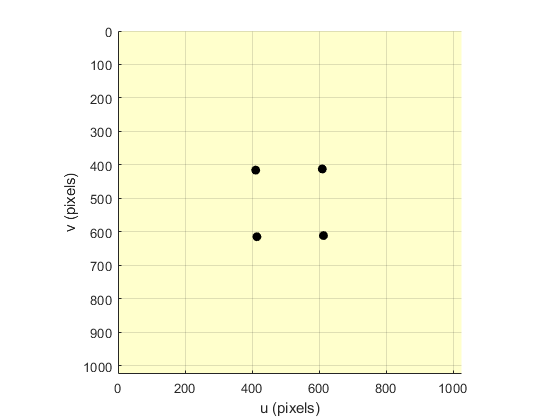

Error due to multiple causes.
Caused by:
    Error using chap16 (line 14)
    Error in 'sl_arm_ibvs/plot/S-Function' while executing MATLAB S-function 'slplotbot', flag = 3 (output), at time 3.7600000000000002.
        Error using chap16 (line 14)
        Unrecognized function or variable 'h'.
    Error using 

sl_arm_ibvs

r = sim('sl_arm_ibvs')


q = squeeze(r.find('yout').signals(1).values)';
about(q)

## 16.4.3 Application: Aerial Robot

----- creating workspace variables: camera, quad, P, pstar
principal point not specified, setting it to centre of image plane


creating new figure for camera


h =   Axes with properties:

             XLim: [0 1]
             YLim: [0 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties

make axes


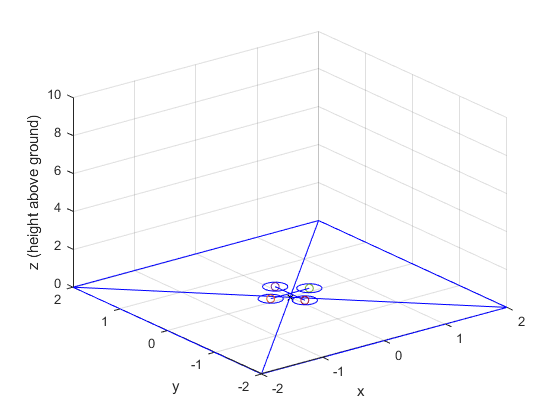

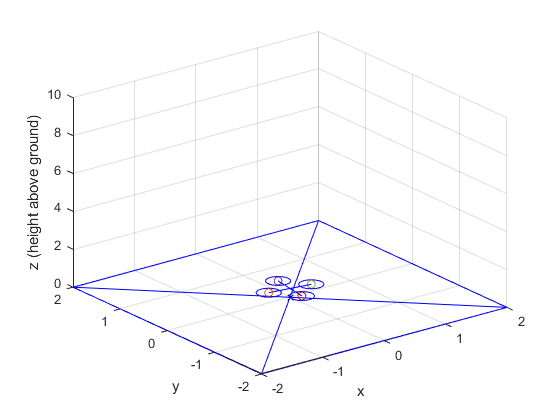

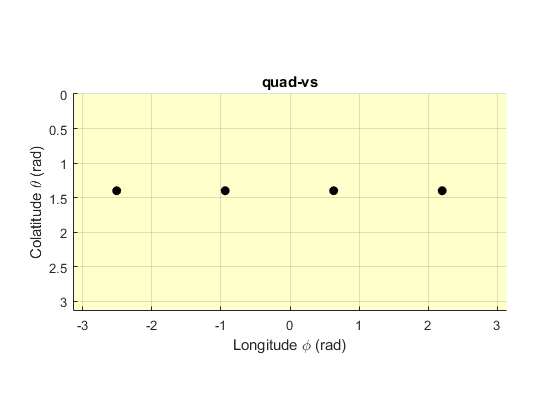

Error due to multiple causes.
Caused by:
    Error using chap16 (line 44)
    Program interruption (Ctrl-C) has been detected.
    Error using chap16 (line 44)
    Error in 'sl_quadrotor_vs/camera/MATLAB Fcn' while evaluating expression.

sl_quadrotor_vs

sim('sl_quadrotor_vs')